## 2.2.1

differentiator: y[n]=x[n]-x[n-1]

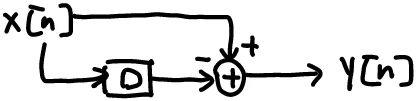

integrator: y[n]=y[n-1]+x[n]

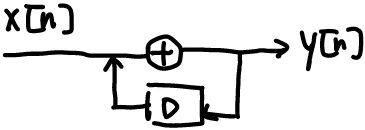

## 2.2.2

avgvalue[today] =  1/3 (value[today] + value[yesterday] + value[2 days ago]) 

y[n] = 1/3*x[n] + x[n-1] + x[n-2]    

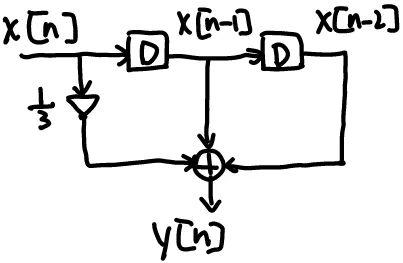

n = -5:1:5;
x = [zeros(1,5) 1 zeros(1,5)];
y1 = zeros(1,11);
y2 = zeros(1,11);
y3 = zeros(1,11);
figure;
for k = 3:11
    y1(k) = 1/3*(x(k)+x(k-1)+x(k-2));
end
subplot(3,1,1),stem(n,y1),title('Impulse Response 1','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');

avgvalue[today] = 0.8 * avgvalue[yesterday] + 0.2 * (value[today]) 

y[n] = 0.8*y[n-1] + 0.2*x[n]

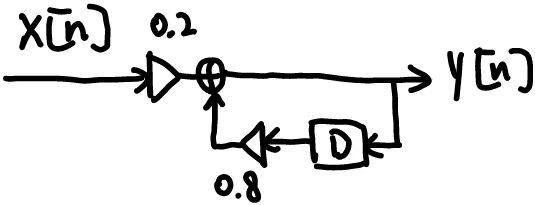

for k = 2:11
    y2(k) = 0.8*y2(k-1)+0.2*x(k);
end
subplot(3,1,2),stem(n,y2),title('Impulse Response 2','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');

avgvalue[today] = avgvalue[yesterday] + 1/3 (value[today]-(value[3 days ago])

y[n] = y[n-1] + 1/3*x[n] - 1/3*x[n-3]

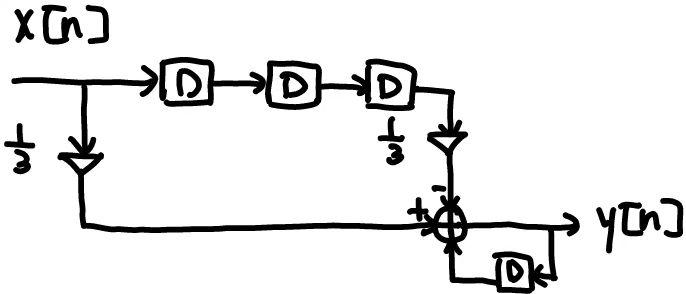

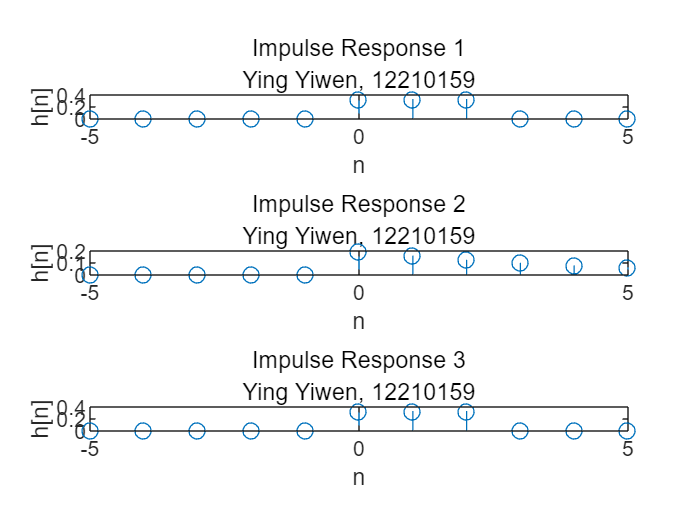

for k = 4:11
    y3(k) = y3(k-1) + 1/3*x(k) -1/3*x(k-3);
end
subplot(3,1,3),stem(n,y3),title('Impulse Response 3','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');

Method(2.3), (2.5) use delayed components like x[n-3], x[n-2], x[n-1], and they have coefficients to average the value, so they are moving average.

## 2.3

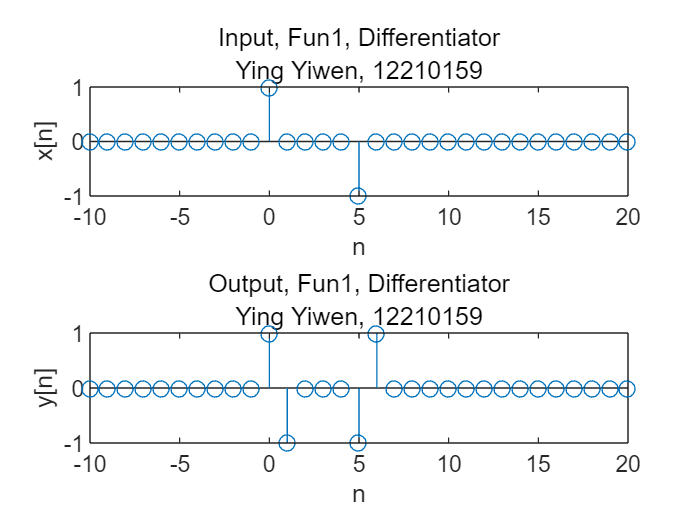

n = -10:1:20;
% fun1
x = [zeros(1,10), 1, zeros(1,4), -1, zeros(1,15)];
% fun1, differentiator
y1 = zeros(1,31);
for k = 2:31
    y1(k) = x(k) - x(k-1);
end
figure;
subplot(2,1,1),stem(n,x),title('Input, Fun1, Differentiator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('x[n]');
subplot(2,1,2),stem(n,y1),title('Output, Fun1, Differentiator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('y[n]');

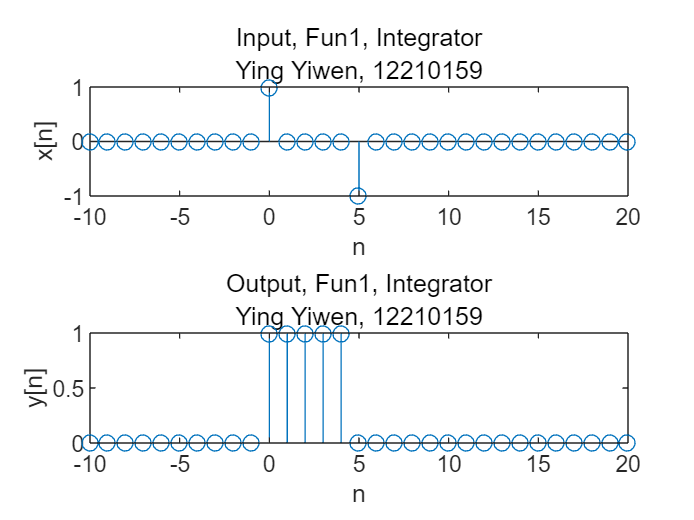

% fun1, integrator
y2 = zeros(1,31);
for k = 2:31
    y2(k) = y2(k-1) + x(k);
end
figure;
subplot(2,1,1),stem(n,x),title('Input, Fun1, Integrator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('x[n]');
subplot(2,1,2),stem(n,y2),title('Output, Fun1, Integrator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('y[n]');

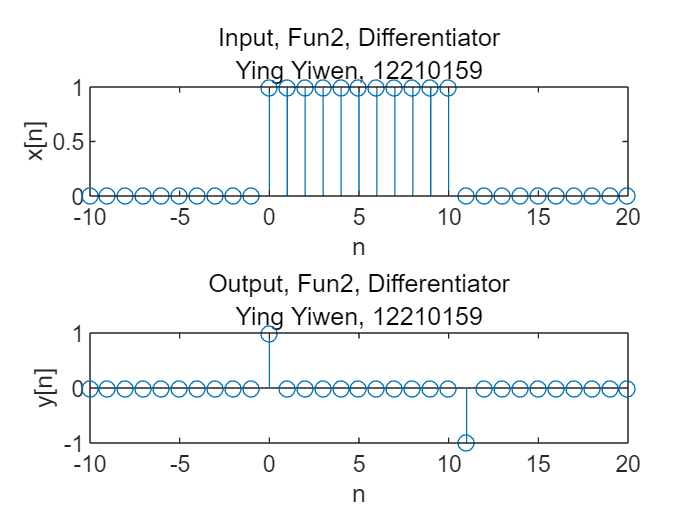


% fun2
N = 10;
x = (n>=0) - (n>=N+1);
% fun2, differentiator
y1 = zeros(1,31);
for k = 2:31
    y1(k) = x(k) - x(k-1);
end
figure;
subplot(2,1,1),stem(n,x),title('Input, Fun2, Differentiator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('x[n]');
subplot(2,1,2),stem(n,y1),title('Output, Fun2, Differentiator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('y[n]');

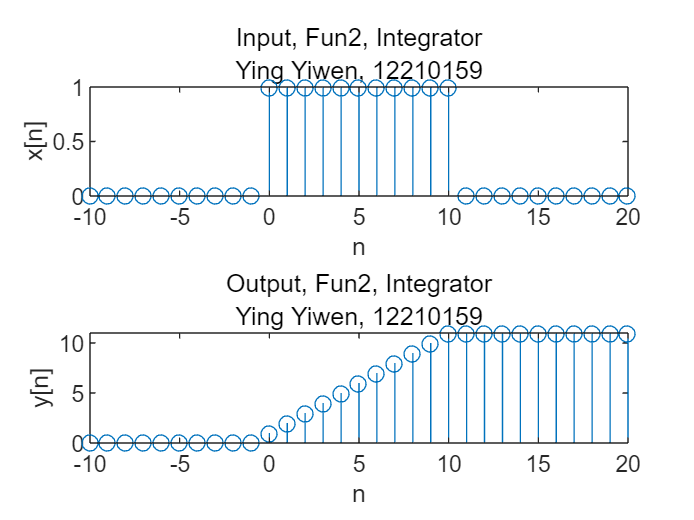

% fun2, integrator
y2 = zeros(1,31);
for k = 2:31
    y2(k) = y2(k-1) + x(k);
end
figure;
subplot(2,1,1),stem(n,x),title('Input, Fun2, Integrator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('x[n]');
subplot(2,1,2),stem(n,y2),title('Output, Fun2, Integrator','Ying Yiwen, 12210159'),xlabel('n'),ylabel('y[n]');

## 2.4

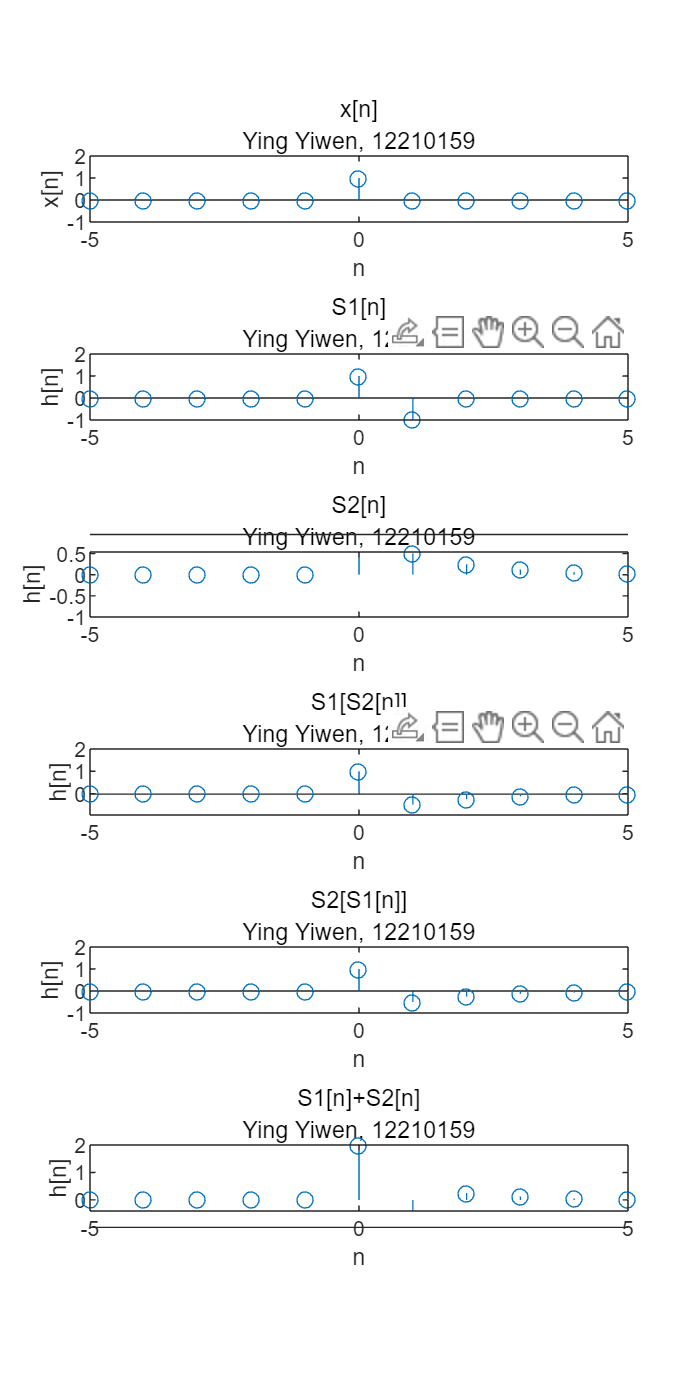

% functions are at the bottom
n = -5:1:5;
x = [zeros(1,5) 1 zeros(1,5)];
y1 = S1(x);
y2 = S2(x);
y3 = S1(y2);
y4 = S2(y1);
y5 = S1(x)+S2(x);
figure;
set(gcf, 'Position', [0, 0, 560, 1120]);
subplot(6,1,1),stem(n,x),xlabel('n'),ylabel('x[n]'),title('x[n]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(6,1,2),stem(n,y1),xlabel('n'),ylabel('h[n]'),title('S1[n]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(6,1,3),stem(n,y2),xlabel('n'),ylabel('h[n]'),title('S2[n]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(6,1,4),stem(n,y3),xlabel('n'),ylabel('h[n]'),title('S1[S2[n]]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(6,1,5),stem(n,y4),xlabel('n'),ylabel('h[n]'),title('S2[S1[n]]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(6,1,6),stem(n,y5),xlabel('n'),ylabel('h[n]'),title('S1[n]+S2[n]','Ying Yiwen, 12210159'),ylim([-1 2]);

S1[n]

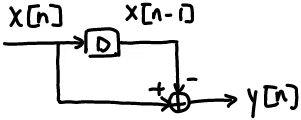

S2[n]

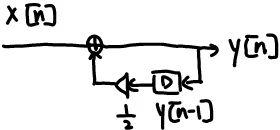

S1[S2[n]]

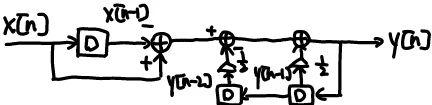

S2[S1[n]]

S1[n]+S2[n]

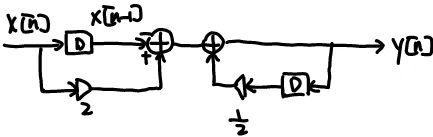

## 2.5

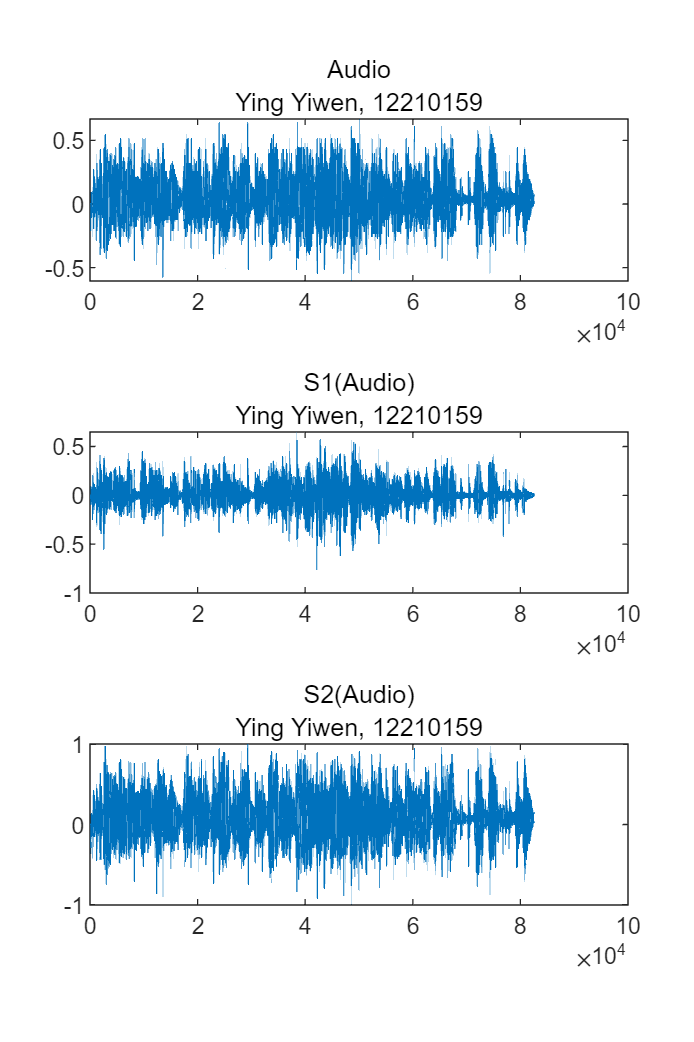

audio = audioread("music.au");
sound(audio);
filtered1 = S1(audio);
sound(filtered1);
filtered2 = S2(audio);
sound(filtered2);
figure;
set(gcf, 'Position', [0, 0, 560, 840]);
subplot(3,1,1),plot(audio),title('Audio','Ying Yiwen, 12210159');
subplot(3,1,2),plot(filtered1),title('S1(Audio)','Ying Yiwen, 12210159');
subplot(3,1,3),plot(filtered2),title('S2(Audio)','Ying Yiwen, 12210159');

S1 makes the audio more screechy, S2 makes the audio more flat

## 2.6

S3: y[n] = x[n] - 0.5*x[n-1] 

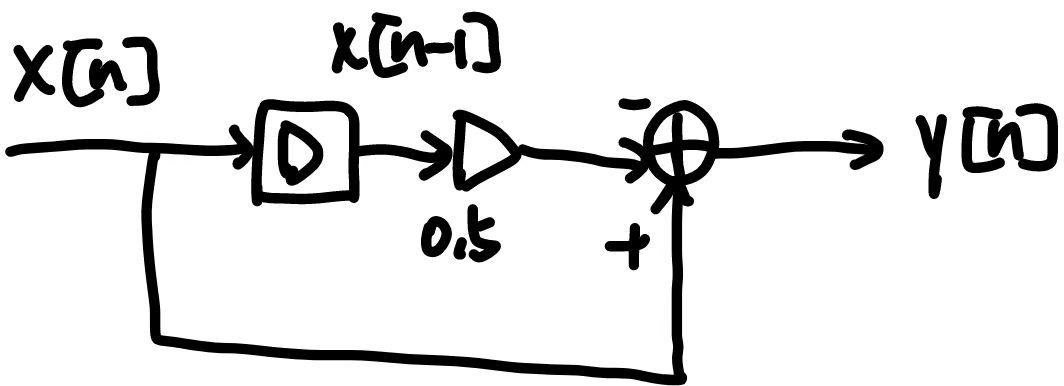

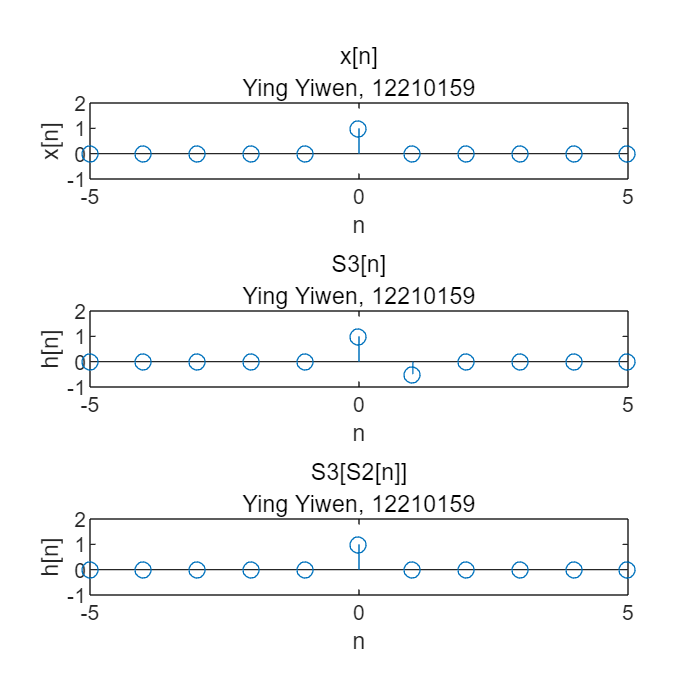

n = -5:1:5;
x = [zeros(1,5) 1 zeros(1,5)];
y1 = S3(x);
y2 = S3(S2(x));
figure;
set(gcf, 'Position', [0, 0, 560, 560]);
subplot(3,1,1),stem(n,x),xlabel('n'),ylabel('x[n]'),title('x[n]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(3,1,2),stem(n,y1),xlabel('n'),ylabel('h[n]'),title('S3[n]','Ying Yiwen, 12210159'),ylim([-1 2]);
subplot(3,1,3),stem(n,y2),xlabel('n'),ylabel('h[n]'),title('S3[S2[n]]','Ying Yiwen, 12210159'),ylim([-1 2]);

## 2.7

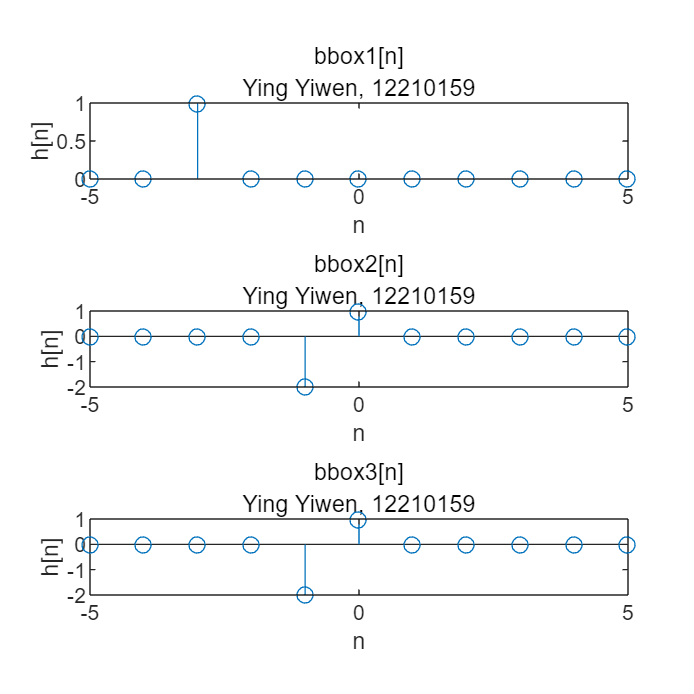

addpath('bbox_p');
n = -5:1:5;
x = [zeros(1,4) 0 1 zeros(1,5)];
y1 = bbox1(x);
y2 = bbox2(x);
y3 = bbox3(x);
figure;
set(gcf, 'Position', [0, 0, 560, 560]);
subplot(3,1,1),stem(n,y1),xlabel('n'),ylabel('h[n]'),title('bbox1[n]','Ying Yiwen, 12210159');
subplot(3,1,2),stem(n,y2),xlabel('n'),ylabel('h[n]'),title('bbox2[n]','Ying Yiwen, 12210159');
subplot(3,1,3),stem(n,y3),xlabel('n'),ylabel('h[n]'),title('bbox3[n]','Ying Yiwen, 12210159');

bbox1 is time-varying, the plot 2 should be 1 unit at the right of plot 1, but it isn't

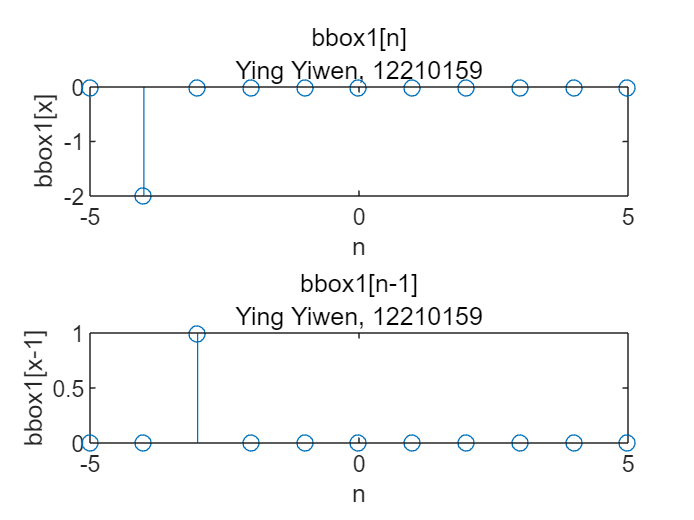

x1 = [zeros(1,4) 1 zeros(1,6)];
x2 = [zeros(1,5) 1 zeros(1,5)];
y1 = bbox1(x1);
y2 = bbox1(x2);
figure;
subplot(2,1,1),stem(n,y1),xlabel('n'),ylabel('bbox1[x]'),title('bbox1[n]','Ying Yiwen, 12210159');
subplot(2,1,2),stem(n,y2),xlabel('n'),ylabel('bbox1[x-1]'),title('bbox1[n-1]','Ying Yiwen, 12210159');

bbox3 isn't linear, the plot 2 should be twice as the plot 1, but it isn't

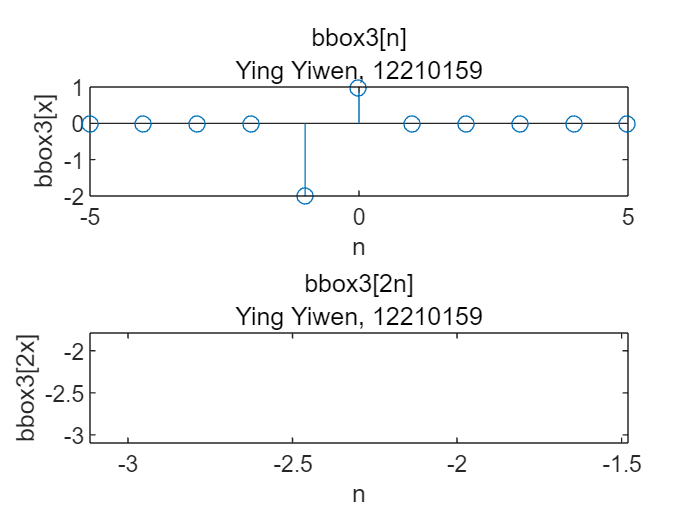

x1 = [zeros(1,5) 1 zeros(1,5)];
x2 = [zeros(1,5) 2 zeros(1,5)];
y1 = bbox3(x1);
y2 = bbox3(x2);
figure;
subplot(2,1,1),stem(n,y1),xlabel('n'),ylabel('bbox3[x]'),title('bbox3[n]','Ying Yiwen, 12210159');
subplot(2,1,2),stem(n,y2),xlabel('n'),ylabel('bbox3[2x]'),title('bbox3[2n]','Ying Yiwen, 12210159');

## 2.8

load stockrates.mat;
x = rate

x =    46.5000   47.5000   47.5000   47.0000   46.1250   45.2500   45.7500   45.8750   45.6250   44.7500   44.3750   44.7500   44.7500   46.5000   46.5000   47.6250   47.7500   48.1250   48.8750   48.0000   49.7500   49.8750   45.0000   46.0000   46.0000   45.5000   44.6250   43.7500   44.2500   44.3750   44.1250   43.2500   42.8750   43.2500   43.2500   45.0000   45.0000   46.1250   46.2500   46.6250   47.3750   46.5000   48.2500   48.3750


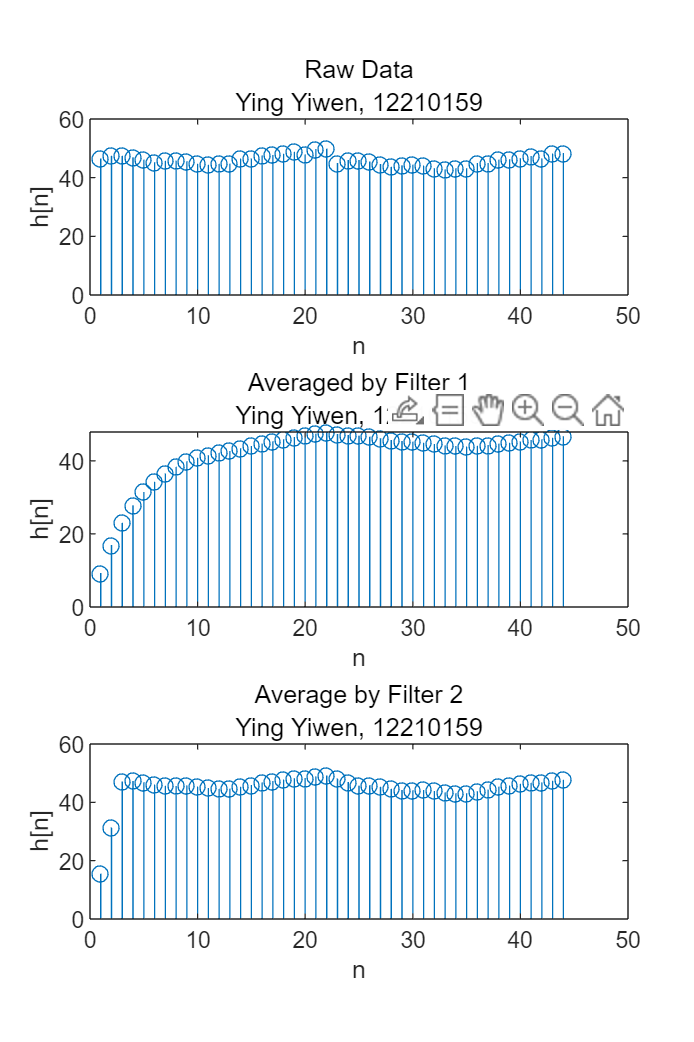

n = 1:1:length(rate);
figure;
set(gcf, 'Position', [0, 0, 560, 840]);
subplot(3,1,1),stem(n,x),title('Raw Data','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');
y1(1) = 0.2*x(1);
for k = 2:length(rate)
    y1(k) = 0.8*y1(k-1)+0.2*x(k);
end
subplot(3,1,2),stem(n,y1),title('Averaged by Filter 1','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');
y2(1) = 1/3*x(1);
y2(2) = y2(1) + 1/3*x(2);
y2(3) = y2(2) + 1/3*x(3);
for k = 4:length(rate)
    y2(k) = y2(k-1) + 1/3*x(k) -1/3*x(k-3);
end
subplot(3,1,3),stem(n,y2),title('Average by Filter 2','Ying Yiwen, 12210159'),xlabel('n'),ylabel('h[n]');

## functions

function y = S1(x)
    n = length(x);
    y = zeros(1,n);
    for k = 2:n
        y(k) = x(k) - x(k-1);
    end
end

function y = S2(x)
    n = length(x);
    y = zeros(1,n);
    for k = 2:n
        y(k) = 0.5 * y(k-1) + x(k);
    end
end

function y = S3(x)
    n = length(x);
    y = zeros(1,n);
    for k = 2:n
        y(k) = x(k) - 0.5 * x(k-1);
    end
end